# 需求分析：粒子群算法求解函数极值问题

#### 假设搜索控件维度为D，粒子数为N

- 第 i 个粒子位置表示为：$X_i = (x_{i1},x_{i2},...,x_{iD})$

- 第 i 个粒子速度表示为：$V_i = (v_{i1},v_{i2},...,v_{iD})$

- 第 i 个粒子迄今为止搜索到的最优位置称为个体极值：$p_{best}= (p_{i1},p_{i2},...,p_{iD})$

- 所有粒子迄今为止搜索到的最优位置称为全局极值：$g_{best}= (g_1,g_2,...,g_D)$

#### 基本粒子群进化过程

- 
$$v_{ij}(t+1)=v_{ij}(t)+c_1*r_1(t)*(p_{ij}(t) - x_{ij}(t))+c_2*r_2(t)*(p_{gj}(t) - x_{ij}(t))$$


- 
$$x_{ij}(t+1)=x_{ij}(t)+v_{ij}(t+1)$$


#### 标准粒子群进化过程

- 
$$v_{ij}(t+1)=w*v_{ij}(t)+c_1*r_1(t)*(p_{ij}(t) - x_{ij}(t))+c_2*r_2(t)*(p_{gj}(t) - x_{ij}(t))$$


- 
$$x_{ij}(t+1)=x_{ij}(t)+v_{ij}(t+1)$$


- 惯性权重线性递减策略：$w=w_{max}-\frac{w_{max}-w_{min}}{T_{max}}*t$，一般取$w_{max}=0.9,w_{min}=0.4$

#### 压缩因子粒子群进化过程

- 
$$v_{ij}(t+1)=\lambda*v_{ij}(t)+c_1*r_1(t)*(p_{ij}(t) - x_{ij}(t))+c_2*r_2(t)*(p_{gj}(t) - x_{ij}(t))$$


- 
$$\lambda=\frac{2}{|2-\phi-\sqrt{\phi^2-4\phi}|},\phi=c_1+c_2$$


clear; clc;
% 群体粒子个数
N = 200;   
% 粒子维度
D = 2;    
% 最大迭代次数
T = 200;      
% 学习因子1
c1 = 1.5;    
% 学习因子2
c2 = 1.5;   
% 惯性权重最大值
wMax = 0.8;   
% 惯性权重最小值
wMin = 0.4;      
% 位置最大值
xMax = 10 * ones(1, D);  
% 位置最小值
xMin = -10 * ones(1, D); 
% 速度最大值
vMax = 1; 
% 速度最小值
vMin = -1;            
%%%%%%%%%%  初始化种群个体（限定位置和速度） %%%%%%%%%
x = rand(N, D) .* repmat(xMax - xMin, N, 1) + repmat(xMin, N, 1);
v = rand(N, D) * (vMax - vMin) + vMin;
%%%%%%%%%%  初始化个体最优位置和最优值 %%%%%%%%%
p = x;
pbest = ones(N, 1);
for i = 1 : N
   pbest(i) = ObjFun(x(i, :));
end
%%%%%%%%%%  初始化全局最优位置和最优值 %%%%%%%%%
g = ones(1, D);
gbest = inf;
for i = 1 : N
   if pbest(i) < gbest
      g = p(i, :);
      gbest = pbest(i);
   end
end
gb = ones(1, T);
%%%%%%%%%%  按照公式依次迭代直到满足精度或者迭代次数 %%%%%%%%%
for i = 1 : T
   for j = 1 : N
      %%%%%%%%%%  更新个体最优位置和最优值 %%%%%%%%%
      if ObjFun(x(j, :)) < pbest(j)
         p(j, :) = x(j, :);
         pbest(j) = ObjFun(x(j, :));
      end
      %%%%%%%%%%  更新全局最优位置和最优值 %%%%%%%%%
      if pbest(j) < gbest
         g = p(j, :);
         gbest = pbest(j);
      end
      %%%%%%%%%%  动态计算惯性权重值 %%%%%%%%%
      w = wMax - (wMax - wMin)*i/T;
%       w = Wmin + (Wmax - Wmin)*rand;
      %%%%%%%%%%  更新位置和速度值 %%%%%%%%%
      v(j, :) = w*v(j, :) + c1*rand*(p(j, :) - x(j, :)) + c2*rand*(g - x(j, :));
      x(j, :) = x(j, :) + v(j, :);
      %%%%%%%%%%  边界条件处理 %%%%%%%%%
      for ii = 1:D
         if (v(j, ii) > vMax) || (v(j, ii) < vMin)
            v(j, ii) = rand*(vMax - vMin) + vMin;
         end
         if (x(j, ii) > xMax(ii)) || (x(j, ii) < xMin(ii))
            x(j, ii) = rand*(xMax(ii) - xMin(ii)) + xMin(ii);
         end
      end
   end
      %%%%%%%%%%  记录历代全局最优值 %%%%%%%%%
      gb(i) = gbest;
end
disp(['最优个体：' num2str(g)]);

最优个体：2.1441e-09  1.6252e-09


disp(['最优值：' num2str(gb(end))]);

最优值：0


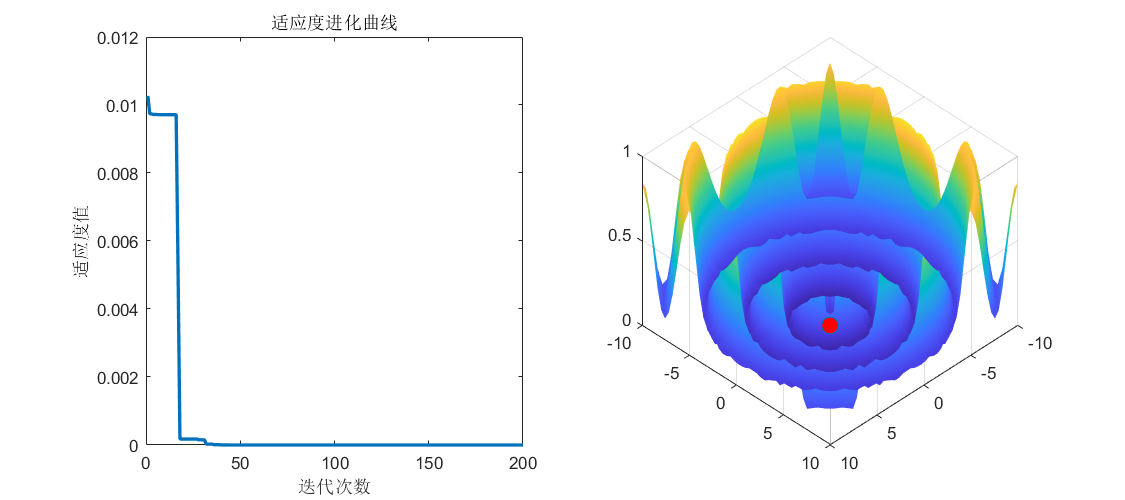

subplot(1, 2, 1)
plot(gb, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('适应度值');
title('适应度进化曲线');
len = 50;
xRange = linspace(xMin(1), xMax(1), len);
yRange = linspace(xMin(2), xMax(2), len);
[xMap, yMap] = meshgrid(xRange, yRange);
zMap = zeros(len);
for i = 1 : len
    for j = 1 : len
        zMap(i, j) = ObjFun([xMap(i, j), yMap(i, j)]);
    end
end
subplot(1, 2, 2)
surf(xRange, yRange, zMap);
view(-45, -45);
shading interp
hold on
plot3(g(1), g(2), ObjFun(g), 'o', 'MarkerFaceColor', 'r', 'MarkerSize', 10);
hold off
set(gcf, 'Position', [400, 200, 900, 400]);

function result = ObjFun(x)
x1 = x(1);
x2 = x(2);
t = x1^2 + x2^2;
result = 0.5 + (sin(sqrt(t))^2 - 0.5) / (1 + 0.001 * t)^2;
end